# Tasks 4

## Preparing the MerchData image dataset

We'll work with the MerchData dataset again. Load the MerchData dataset as an `imageDatastore` using the foldernames as class labels. Divide your `imageDatastore` object into two smaller `imageDatastore` objects, one containing a random 60% of the images in each class for use in training, and one containing the remaining 40% of the images in each class for use in testing:

(**Sanity check**: you have completed these exact same steps before, check over your work from the previous lab if you're struggling, or ask for help)

% check the dataset is present:
if ~exist('./MerchData', 'dir')
    error('You need to download MerchData.zip from Moodle and unzip it into the same directory as this live script');
end

rng(0); % please leave this re-seeding of the random number generator in place so we can compare results
imds = imageDatastore('MerchData','IncludeSubfolders', true,'LabelSource','foldernames');
[training, testing] = splitEachLabel(imds, 0.6, 'randomize')

training =   ImageDatastore with properties:

                       Files: {
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_0.jpg';
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_148.jpg';
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_198.jpg'
                               ... and 42 more
                              }
                     Folders: {
                              '/MATLAB Drive/Examples/mainDir/lab work/MerchData'
                              }
                      Labels: [MathWorks Cap; MathWorks Cap; MathWorks Cap ... and 42 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn

testing =   ImageDatastore with properties:

                       Files: {
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_123.jpg';
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_173.jpg';
                              ' .../Examples/mainDir/lab work/MerchData/MathWorks Cap/Hat_297.jpg'
                               ... and 27 more
                              }
                     Folders: {
                              '/MATLAB Drive/Examples/mainDir/lab work/MerchData'
                              }
                      Labels: [MathWorks Cap; MathWorks Cap; MathWorks Cap ... and 27 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFc

% write your code on the lines below:



## Visualising local gradients in an image

fx = [ -1  0  1;
       -1  0  1;
       -1  0  1 ];

fy = [ -1 -1 -1;
        0  0  0;
        1  1  1];
    
colormap('gray');
%imagesc(fx);
%imagesc(fy);

By performing convolutions with the two filters shown above it's possible to find local gradients in a greyscale image. The word "gradient" in this context just means "steepness" or "slope" and it can be useful to think of the pixel brightnesses in the greyscale image as defining the structure of a 3D surface, where we are interested in the steepness of the slope at every point.

Load the first image in your training `imageDatastore`, and use Matlab's `im2gray()` function to convert it to greyscale. Call `surf()` on the resulting image and use your mouse to rotate around the surface and look for strong gradients/steep slopes:

(**Hint**: set the name-value pair `'EdgeColor', 'none'` for a clearer view). 

%reset(training)
%im = training.readimage(1);
%im = im2gray(im);
%surf(im,'EdgeColor', 'none');



## Computing local gradients in an image

Again load the first image in your training `imageDatastore`, and use Matlab's `im2gray()` function to convert it to greyscale. Pass the resulting image to Matlab's `imgradientxy()` function and ask it to compute local horizontal and vertical gradients using the Prewitt method (which uses the two filters shown in the previous section). Visualise both the horizontal and vertical local gradients by generating images from the resulting arrays:

(**Sanity check**: in one image vertical edges should get the largest scores (bright white or dark black) and in the other image it should be horizontal edges that get the largest scores)

## Image edges I

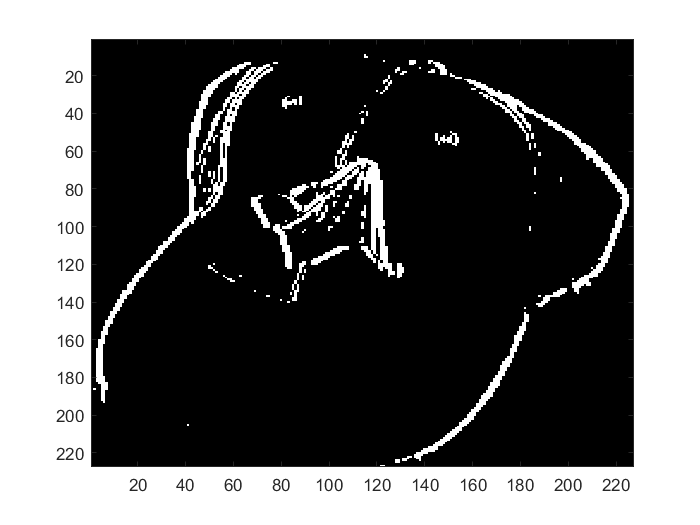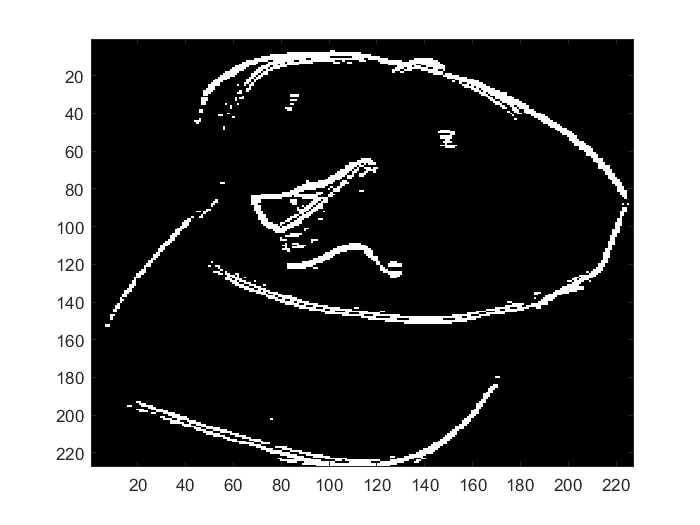

Now let's return to the problem of extracting suitable feature values from our images so that we can attempt to solve ML problems. Last time we tried a single, simple feature based on the overall brightness of the image. This time we'll try thresholding the local gradient magnitudes to look for the presence of vertical or horizontal edges in the image. By magnitude we mean that we are only interested in the strength of the local gradient and not whether it's positive or negative (dark to light, or light to dark), and so we'll drop any minus signs. We'll be computing two "edge features" where we previously computed a single "brightness feature".

For each of the two arrays which resulted from your call to `imgradientxy()` in the previous task, take its magnitude (**hint**: you can use the `abs()` function to do this) and write an expression to generate a logical array containing the values 1 where the magnitude was greater than or equal to a threshold value of 45 and the values 0 where the magnitude was less than 45. Generate images from the two resulting arrays to convince yourself your expressions are working correctly:

(**Sanity check**: If you end up with lots of numbers, look back to how you calculated average brightness in your previous work; check the MF section on logical indexing if you need help constructing the expression; your images should look very similar to the ones above, depending on exactly how you do the visualisation.)

im = training.readimage(1);
im = im2gray(im)

im = 227×227 uint8 matrix
   177   177   177   178   178   179   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   173   173   172   172   172   173   173
   177   177   177   178   178   178   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   173   173   173   172   172   173   173
   177   177   177   177   178   178   178   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   174   173   173   173   172   173   174
   176   176   177   177   177   178   178   178   178   178   178   17

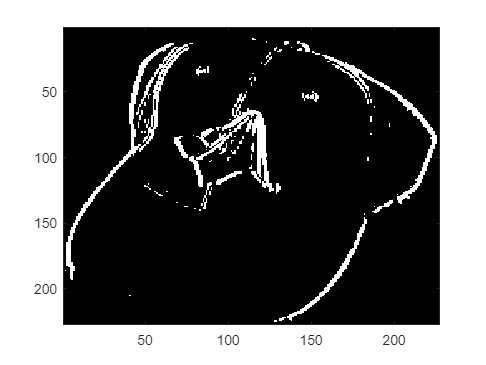


[Gx, Gy] = imgradientxy(im,'prewitt');

Gx = abs(Gx);
Gy = abs(Gy);

threshold = 45; 

Gx = Gx >= threshold;
Gy = Gy >= threshold;

imagesc(Gx)

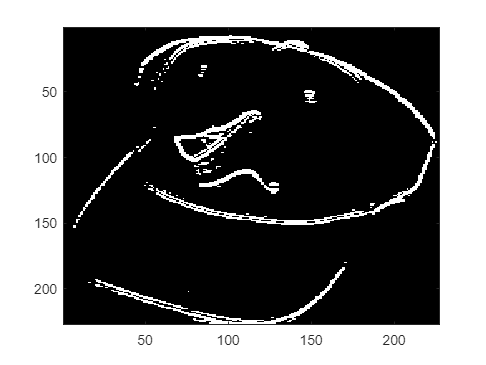

imagesc(Gy)

Now extract a single number from each logical array, giving the fraction of pixels which we believe contain an edge; i.e., the total number of 1s generated by the thresholding process above, divided by the total number of elements in the array:

(**Sanity check**: you should get the values 0.0576 and 0.0599)

total1s = sum(Gx(:) == 1)

total1s = 2970


totalElements = numel(Gx);

total1s / totalElements 

ans = 0.0576


numel(Gy) \ sum(Gy(:) == 1)

ans = 0.0599

## Image edges II

Now reuse your code from the previous task to extend the `get_edges()` function stub so that for any image passed in, it converts it to greyscale, computes local gradients by calling `imgradientxy()`, thresholds the magnitudes in the two resulting arrays in order to generate estimates of the fraction of pixels containing vertical and horizontal edges respectively, and returns a 2-element array containing those two "edge features". Add code below to pass the first image in your training `imageDatastore` to your new function and convince yourself that it returns the correct answer:

(**Sanity check**: the answer you get back from your function should match the numbers you got in the previous task)

im = training.readimage(1);
get_edges(im)

ans =     0.0576    0.0599


## Extracting training data

The `Labels` property of your training `imageDatastore` contains the class labels for each of your training images, in order. Copy it into a variable called `train_labels`. Now by looping over the images in your training `imageDatastore`, and calling your `get_edges()` function with each one, construct an array of corresponding edge features called `train_examples`. If you're struggling, consider checking the Matlab fundamentals for a reminder of how you can grow arrays downwards, checking the reusable code in the lecture slides, or having a play around in the Command Window to remind yourself:

(**Sanity check**: `train_examples` should be a 2D array, where each row contains the two features for a single training image (so it should have the same height as `train_labels` and a width of 2); if you get something with fewer elements consider whether you need to call `reset()` on your training `imageDatastore`)

% <my comment removed>:
train_examples = [];

train_labels = training.Labels;

while hasdata(training)
    % <my comment removed>:
    im = im2gray(training.read());
    % usually, we’ll move our feature extraction
    % work out into its own separate function:
    train_examples(end+1,:) = get_edges(im);
    
end 


## Train and evaluate an image classifier

Use the `train_examples` and `train_labels` arrays you created in the previous task to call `fitcknn()` and train a k-NN classifier with k=3 neighbours. Next, build `test_examples` and `test_labels` arrays from your testing data in just the same way you did for the previous task, and use these new arrays to evaluate your classifier's performance by computing a confusion matrix and overall classification accuracy.

(**Sanity check**: you should expect a small performance improvement on the brightness-based approach from the previous task sheet: 53.3%)

test_labels = testing.Labels;
test_examples = [];

while hasdata(testing)
    im = im2gray(testing.read());
    test_examples(end+1,:) = get_edges(im)
end

test_examples =     0.0202    0.0221


test_examples =     0.0202    0.0221
    0.0154    0.0476


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


test_examples =     0.0202    0.0221
    0.0154    0.0476
    0.0195    0.0326
    0.0373    0.0461
    0.0394    0.0552
    0.0385    0.0586
    0.0572    0.0517
    0.1304    0.1377
    0.0705    0.0663
    0.0634    0.0821


kNN = fitcknn(train_examples,train_labels,"NumNeighbors",3);

predictions = predict(kNN,test_examples);
    
[c, order] = confusionmat(test_labels, predictions);
    
p = sum(diag(c)) / sum(c(1:1:end)) * 100

p = 53.3333

## Extension task: implementing local gradient computation

This task is about coding up the convolutions we've been using above for yourself. Try implementing the `my_imgradientxy()` function stub so that for any grayscale image passed in, it computes the two arrays of local gradients by performing the necessary convolutions between the image and the relevant Prewitt filters.

We suggest that as a first step, you use `imfilter()` to do the convolutions for you, and check that you can get exactly the same result from your `my_imgradientxy()` function as you get from the built-in `imgradientxy()` function. 

We recommend testing with a small, randomly set matrix, so you can easily compare results visually in the Command Window (if you work with a whole image straight away then you'll be overwhelmed by data):

im = training.readimage(1)

im = 227×227×3 uint8 array
im(:,:,1) =

   163   163   163   164   164   165   165   165   164   164   164   164   164   164   164   164   165   165   164   163   163   162   161   161   161   161   161   161   161   161   161   161   162   161   161   160   160   161   161   162   161   161   161   160   160   159   159   159   160   160   160   161   163   164   165   165   168   168   170   170   171   171   171   171   170   170   168   168   167   167   165   165   162   161   161   160   159   159   160   161   163   165   166   166   166   166   167   167   168   168   168   168   168   168   168   166   170   168   168   169   170   172   175   177   172   171   170   169   169   169   169   169   172   171   171   170   168   167   165   165   168   168   168   168   168   168   168   168   172   172   172   173   173   174   174   174   174   174   174   174   174   174   174   175   178   179   178   178   178   179   179   179   181   178   178   175   175   171   169   169

im = im2gray(im)

im = 227×227 uint8 matrix
   177   177   177   178   178   179   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   173   173   172   172   172   173   173
   177   177   177   178   178   178   179   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   173   173   173   172   172   173   173
   177   177   177   177   178   178   178   179   178   178   178   178   178   178   178   178   178   178   177   176   176   175   174   174   174   174   174   174   174   174   174   174   175   174   174   173   173   174   174   175   174   174   174   174   173   173   173   172   173   174
   176   176   177   177   177   178   178   178   178   178   178   17



test = round(abs(rand(5,5)) .* 255);

[Gx1, Gy1] = imgradientxy(im,'prewitt');

[g,h] = imgradient(Gx1, Gy1)

g =          0         0    3.0000    3.0000    2.2361    3.1623    1.4142    3.0000    3.0000         0         0         0         0         0         0         0         0    3.0000    6.0000    3.0000    3.0000    6.0000    3.0000         0         0         0         0         0         0         0         0    3.0000         0    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000         0    3.0000         0    3.0000    3.0000    2.2361    3.1623    1.4142    3.0000    3.0000    1.4142
         0         0    2.2361    3.1623    2.8284    2.8284    2.8284    2.2361    3.0000         0         0         0         0         0         0         0         0    3.0000    6.0000    3.0000    3.0000    6.0000    3.0000         0         0         0         0         0         0         0         0    3.0000         0    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000         0    3.0000         0    2.2361    3.1623    2.8284    2.8284    2.8284    2.2361    4.1231    2

h =          0         0         0         0   26.5651   18.4349   45.0000 -180.0000 -180.0000         0         0         0         0         0         0         0         0 -180.0000 -180.0000 -180.0000 -180.0000 -180.0000 -180.0000         0         0         0         0         0         0         0         0         0         0 -180.0000 -180.0000 -180.0000         0         0         0         0 -180.0000         0 -180.0000 -180.0000 -153.4349 -161.5651 -135.0000         0         0  -45.0000
         0         0   26.5651   18.4349   45.0000   45.0000   45.0000  153.4349 -180.0000         0         0         0         0         0         0         0         0 -180.0000 -180.0000 -180.0000 -180.0000 -180.0000 -180.0000         0         0         0         0         0         0         0         0         0         0 -180.0000 -180.0000 -180.0000         0         0         0         0 -180.0000         0 -153.4349 -161.5651 -135.0000 -135.0000 -135.0000  -26.5651  -14.0362  -45


[Gmag,Gdir] = my_imgradient(Gx1, Gy1)

Gmag =          0         0    3.0000    3.0000    2.2361    3.1623    1.4142    3.0000    3.0000         0         0         0         0         0         0         0         0    3.0000    6.0000    3.0000    3.0000    6.0000    3.0000         0         0         0         0         0         0         0         0    3.0000         0    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000         0    3.0000         0    3.0000    3.0000    2.2361    3.1623    1.4142    3.0000    3.0000    1.4142
         0         0    2.2361    3.1623    2.8284    2.8284    2.8284    2.2361    3.0000         0         0         0         0         0         0         0         0    3.0000    6.0000    3.0000    3.0000    6.0000    3.0000         0         0         0         0         0         0         0         0    3.0000         0    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000         0    3.0000         0    2.2361    3.1623    2.8284    2.8284    2.8284    2.2361    4.1231  

Gmag =          0         0    3.0000    3.0000    2.2361    3.1623    1.4142    3.0000    3.0000         0         0         0         0         0         0         0         0    3.0000    6.0000    3.0000    3.0000    6.0000    3.0000         0         0         0         0         0         0         0         0    3.0000         0    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000         0    3.0000         0    3.0000    3.0000    2.2361    3.1623    1.4142    3.0000    3.0000    1.4142
         0         0    2.2361    3.1623    2.8284    2.8284    2.8284    2.2361    3.0000         0         0         0         0         0         0         0         0    3.0000    6.0000    3.0000    3.0000    6.0000    3.0000         0         0         0         0         0         0         0         0    3.0000         0    3.0000    3.0000    3.0000    3.0000    3.0000    3.0000         0    3.0000         0    2.2361    3.1623    2.8284    2.8284    2.8284    2.2361    4.1231  

Gdir =          0         0         0         0   26.5651   18.4349   45.0000 -180.0000 -180.0000         0         0         0         0         0         0         0         0 -180.0000 -180.0000 -180.0000 -180.0000 -180.0000 -180.0000         0         0         0         0         0         0         0         0         0         0 -180.0000 -180.0000 -180.0000         0         0         0         0 -180.0000         0 -180.0000 -180.0000 -153.4349 -161.5651 -135.0000         0         0  -45.0000
         0         0   26.5651   18.4349   45.0000   45.0000   45.0000  153.4349 -180.0000         0         0         0         0         0         0         0         0 -180.0000 -180.0000 -180.0000 -180.0000 -180.0000 -180.0000         0         0         0         0         0         0         0         0         0         0 -180.0000 -180.0000 -180.0000         0         0         0         0 -180.0000         0 -153.4349 -161.5651 -135.0000 -135.0000 -135.0000  -26.5651  -14.0362  


Gmag == g

ans = 227×227 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1





%[Gx, Gy] = my_imgradientxy(im);



% % example testing 'image':

% % result you're trying to recreate:
% [Gx, Gy] = imgradientxy(test,'prewitt');
% 
% 
% 
% %local graident filters for equations (prewitt)
% 
% GxFil = [-1 0 1
%         -1 0 1
%         -1 0 1];
% 
% GyFil = [-1 -1 -1
%          0 0 0
%          1 1 1];
% 
% % add padding
% 
% % one row deeper:
% test(end+1,:) = test(end,1:1:end);
% 
% % one column to the right:
% test(:,end+1) = test(1:1:end,end);
% 
% % one column to the left:
% test = [test(1:1:end,1) test(1:1:end,1:1:end)];
% 
% % one row to the top:
% test = [test(1,1:1:end); test];
% 
% GxNew = [];
% GyNew = [];
% 
% %loop over image for graident check
% for i=1:1:size(test,1)
%     for j=1:1:size(test,2)
% 
%        if(j+2 <= size(test,1) && i+2 <= size(test,1))
%             A = test(i:i+2,j:j+2);
% 
%             PreX = GxFil.*A;
%             PreY = GyFil.*A;
% 
%             GxNew(i,j) =sum(sum(PreX));
%             GyNew(i,j) =sum(sum(PreY));
% 
%        
%        end
%     end
% 
% end 
% Gx;
% GxNew;
% 
% Gy;
% GyNew;
% 
% 
% 
% [Gx, Gy] = my_imgradientxy(im)
% 
% im = im2gray(im);
% im = im2double(im);
% [Gx2, Gy2] = imgradientxy(im,'prewitt')
% 
% imagesc(Gx2)
% imagesc(Gx)
% 
% imagesc(Gy2)
% imagesc(Gy)
% 
% isequal(Gy,Gy2)
% isequal(Gx,Gx2)
% 
% Gx ~= Gx2
% 
% Gy ~= Gy2

%f = [-1 0 1];
%Rx = imfilter(test, f,'replicate')

%f = [-1 
%    0 
%    1];

%Ry = imfilter(test, f,'replicate')

%

Once you have identical behaviour, try to replace your calls to `imfilter()` with your own code that performs the convolutions manually. Remember that performing the convolutions is as easy as repeating an element-by-element matrix multiplication centred on each brightness value in your image, but to get results right at the edges of your image, you will need to add padding by copying the closest pixel values.

We suggest starting off without worrying about padding, and begin your convolutions 1 column in from the left, and 1 row down from the top (and stopping 1 column/row away from the far/bottom edges) of the image. This way you should be able to match `imfilter()` results, just with a missing border of values around the edge; double check all the rest of your results match exactly. Once you're convinced your individual convolutions are working properly, work on the final step of adding the padding around your image to enable you to generate results with convolutions right at the edges.

Finally, substitute the call to `imgradientxy()` in your `get_edges()` function for a call to your new `my_imgradientxy()` function and check that your answers to the earlier tasks -- where you classfied the testing dataset based on two edge features -- still give the exact same classification accuracy. Switch back and forth between calling `imgradientxy()` and `my_imgradientxy()` a few times, re-running this live script each time, to convince yourself you are definitely getting the same overall classification accuracy.